# Irminger 4 CTD Casts

First produces a rough map of the CTD casts from Irminger 4 in the vicinity of OOI assets. Each CTD cast is then plotted for temperature, salinity, and dissolved oxygen. 

Kristen Fogaren 12/3/2020

- Data was downloaded from Alfresco

- Data conversion with Seabird Software

- Processed casts in Python and output to CSV

- Read into Matab as tables

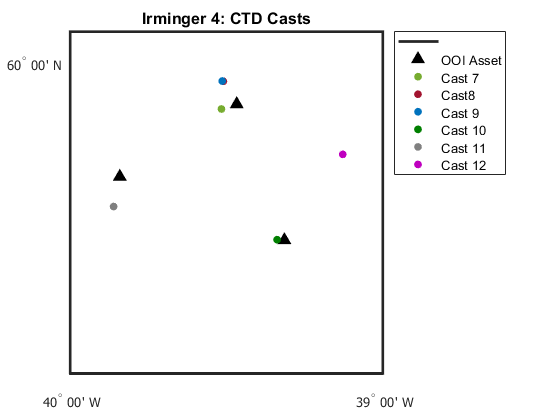

% Set up workspace 
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

cd('G:\My Drive\Matlab_work\BC\IrmingerData\Year4')
load Irm4_CTD_Casts.mat

% OOI asset locations 
ooi_latlon = [59.9341, -39.4673
    59.8177, -39.8412
    59.7155, -39.3148];
    
% Setup the Map Axes
figure
axesm('MapProjection','mercator'); 
minlat=min(ooi_latlon(:,1)); maxlat=max(ooi_latlon(:,1)); 
minlon=min(ooi_latlon(:,2)); maxlon=max(ooi_latlon(:,1)); 

% New Lat/Lon Limits
ll = [-40 59.5; -39 60.05];

setm(gca, 'MapLatLimit',[ll(1,2) ll(2,2)],...
          'MapLonLimit',[ll(1,1) ll(2,1)]);
setm(gca,'MLineLocation',1,'MLabelLocation',1,...
    'MeridianLabel','on','MLabelParallel','south'); 
setm(gca,'PLineLocation',1,'PLabelLocation',1,...
    'ParallelLabel','on','PLabelMeridian','west');
tightmap;
setm(gca,'FontWeight','normal','FontSize',10,'FontName','Tahoma','LabelUnits','dm'); 

% Add lat/lon tickmarks for every degree if the map spans 
% greater than 1.5 degrees longitude, or every quarter degree if less.
if abs(maxlon-minlon)>1.5
  setm(gca,'MLineLocation',1,'MLabelLocation',1,'MeridianLabel','on','MLabelParallel','south'); 
  setm(gca,'PLineLocation',1,'PLabelLocation',1,'ParallelLabel','on','PLabelMeridian','west');
else
  setm(gca,'MLineLocation',0.25,'MLabelLocation',0.25,'MeridianLabel','on','MLabelParallel','south'); 
  setm(gca,'PLineLocation',0.25,'PLabelLocation',0.25,'ParallelLabel','on','PLabelMeridian','west');
end

% Plot Casts/OOI Assets
plotm(ooi_latlon(:,1),ooi_latlon(:,2),'^','markersize',8,'MarkerFaceColor','k',...
    'MarkerEdgeColor','k')
hold on
plotm(nanmean(AR21007down.latitude),nanmean(AR21007down.longitude),'.','markersize',20,'Color',green)
plotm(nanmean(AR21008down.latitude),nanmean(AR21008down.longitude),'.','markersize',20,'Color',maroon)
plotm(nanmean(AR21009down.latitude),nanmean(AR21009down.longitude),'.','markersize',20,'Color',blue)
plotm(nanmean(AR21010down.latitude),nanmean(AR21010down.longitude),'.','markersize',20,'Color',forestgreen)
plotm(nanmean(AR21011down.latitude),nanmean(AR21011down.longitude),'.','markersize',20,'Color',grey)
plotm(nanmean(AR21012down.latitude),nanmean(AR21012down.longitude),'.','markersize',20,'Color',brightpurple)

title('Irminger 4: CTD Casts')
legend('','OOI Asset','Cast 7','Cast8','Cast 9','Cast 10','Cast 11','Cast 12','Location','bestoutside')

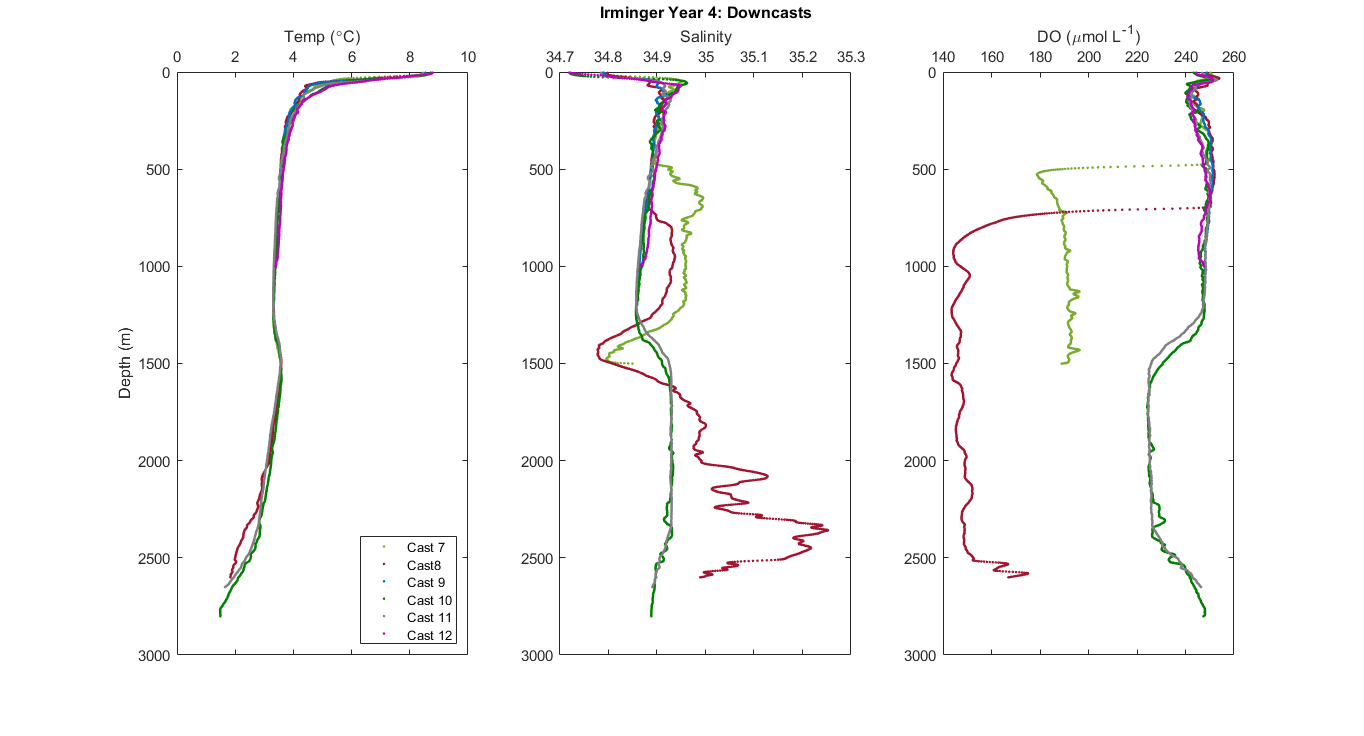

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(AR21007down.t090C,AR21007down.depSM,'.','Color',green)
hold on
plot(AR21008down.t090C,AR21008down.depSM,'.','Color',maroon)
plot(AR21009down.t090C,AR21009down.depSM,'.','Color',blue)
plot(AR21010down.t090C,AR21010down.depSM,'.','Color',forestgreen)
plot(AR21011down.t090C,AR21011down.depSM,'.','Color',grey)
plot(AR21012down.t090C,AR21012down.depSM,'.','Color',brightpurple)
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Cast 7','Cast8','Cast 9','Cast 10','Cast 11','Cast 12','Location','SE')

s2 = subplot(1,3,2);
plot(AR21007down.sal00,AR21007down.depSM,'.','Color',green)
hold on
plot(AR21008down.sal00,AR21008down.depSM,'.','Color',maroon)
plot(AR21009down.sal00,AR21009down.depSM,'.','Color',blue)
plot(AR21010down.sal00,AR21010down.depSM,'.','Color',forestgreen)
plot(AR21011down.sal00,AR21011down.depSM,'.','Color',grey)
plot(AR21012down.sal00,AR21012down.depSM,'.','Color',brightpurple)
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 4: Downcasts')

s3 = subplot(1,3,3);
plot(AR21007down.sbeox0MLL*44.661,AR21007down.depSM,'.','Color',green)
hold on
plot(AR21008down.sbeox0MLL*44.661,AR21008down.depSM,'.','Color',maroon)
plot(AR21009down.sbeox0MLL*44.661,AR21009down.depSM,'.','Color',blue)
plot(AR21010down.sbeox0MLL*44.661,AR21010down.depSM,'.','Color',forestgreen)
plot(AR21011down.sbeox0MLL*44.661,AR21011down.depSM,'.','Color',grey)
plot(AR21012down.sbeox0MLL*44.661,AR21012down.depSM,'.','Color',brightpurple)
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

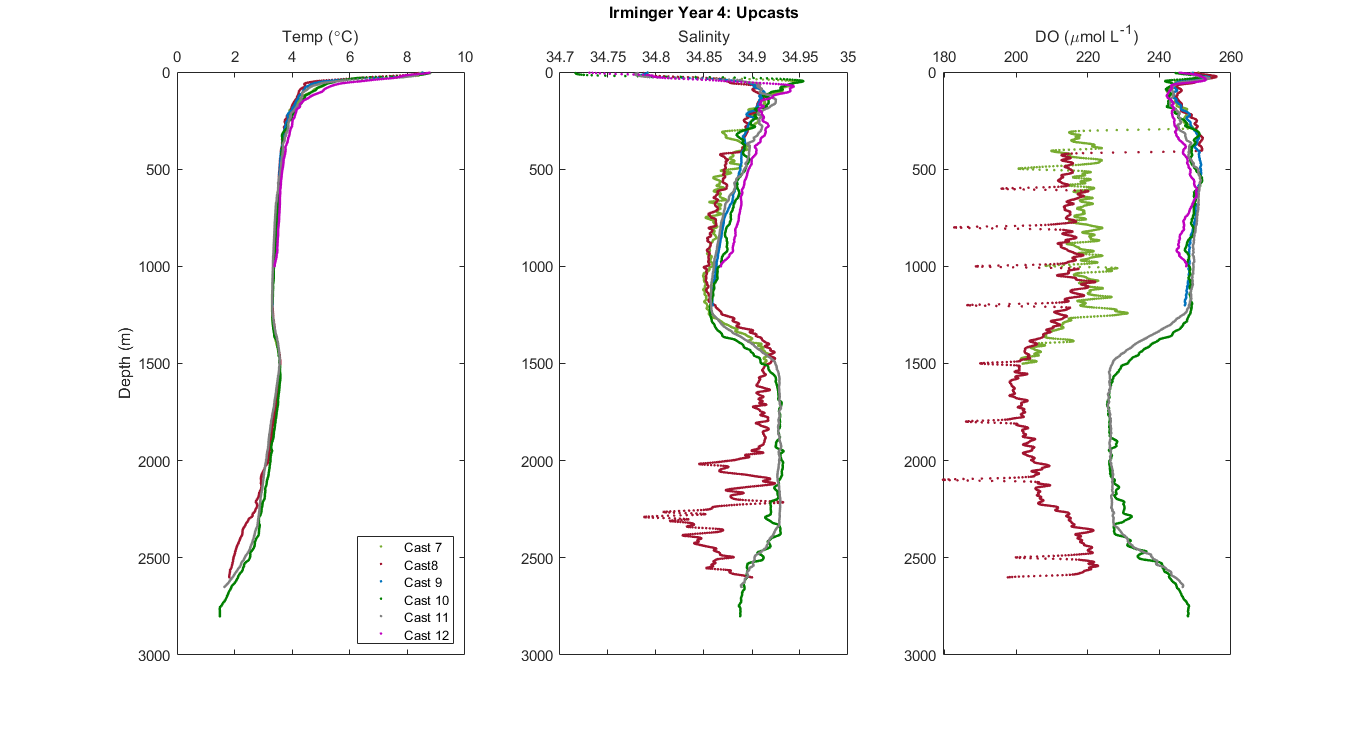

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(AR21007up.t090C,AR21007up.depSM,'.','Color',green)
hold on
plot(AR21008up.t090C,AR21008up.depSM,'.','Color',maroon)
plot(AR21009up.t090C,AR21009up.depSM,'.','Color',blue)
plot(AR21010up.t090C,AR21010up.depSM,'.','Color',forestgreen)
plot(AR21011up.t090C,AR21011up.depSM,'.','Color',grey)
plot(AR21012up.t090C,AR21012up.depSM,'.','Color',brightpurple)
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Cast 7','Cast8','Cast 9','Cast 10','Cast 11','Cast 12','Location','SE')

s2 = subplot(1,3,2);
plot(AR21007up.sal00,AR21007up.depSM,'.','Color',green)
hold on
plot(AR21008up.sal00,AR21008up.depSM,'.','Color',maroon)
plot(AR21009up.sal00,AR21009up.depSM,'.','Color',blue)
plot(AR21010up.sal00,AR21010up.depSM,'.','Color',forestgreen)
plot(AR21011up.sal00,AR21011up.depSM,'.','Color',grey)
plot(AR21012up.sal00,AR21012up.depSM,'.','Color',brightpurple)
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 4: Upcasts')

s3 = subplot(1,3,3);
plot(AR21007up.sbeox0MLL*44.661,AR21007up.depSM,'.','Color',green)
hold on
plot(AR21008up.sbeox0MLL*44.661,AR21008up.depSM,'.','Color',maroon)
plot(AR21009up.sbeox0MLL*44.661,AR21009up.depSM,'.','Color',blue)
plot(AR21010up.sbeox0MLL*44.661,AR21010up.depSM,'.','Color',forestgreen)
plot(AR21011up.sbeox0MLL*44.661,AR21011up.depSM,'.','Color',grey)
plot(AR21012up.sbeox0MLL*44.661,AR21012up.depSM,'.','Color',brightpurple)
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

- Colors in CTD plots correspond to location colors in the map above. 

## Upcasts versus Downcasts 

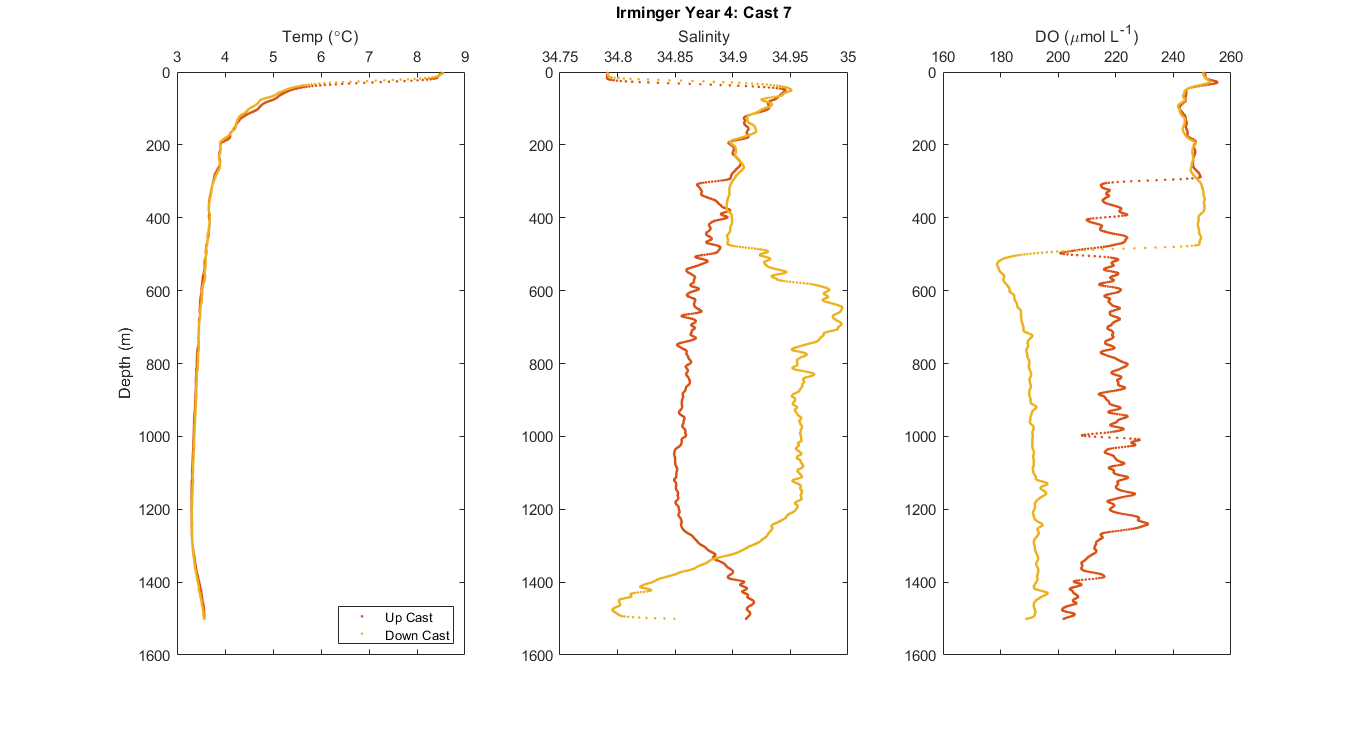


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(AR21007up.t090C,AR21007up.depSM,'.','Color',red);
hold on
plot(AR21007down.t090C,AR21007down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(AR21007up.sal00,AR21007up.depSM,'.','Color',red);
hold on
plot(AR21007down.sal00,AR21007down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 4: Cast 7')

s3 = subplot(1,3,3);
plot(AR21007up.sbeox0MLL*44.661,AR21007up.depSM,'.','Color',red);
hold on
plot(AR21007down.sbeox0MLL*44.661,AR21007down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

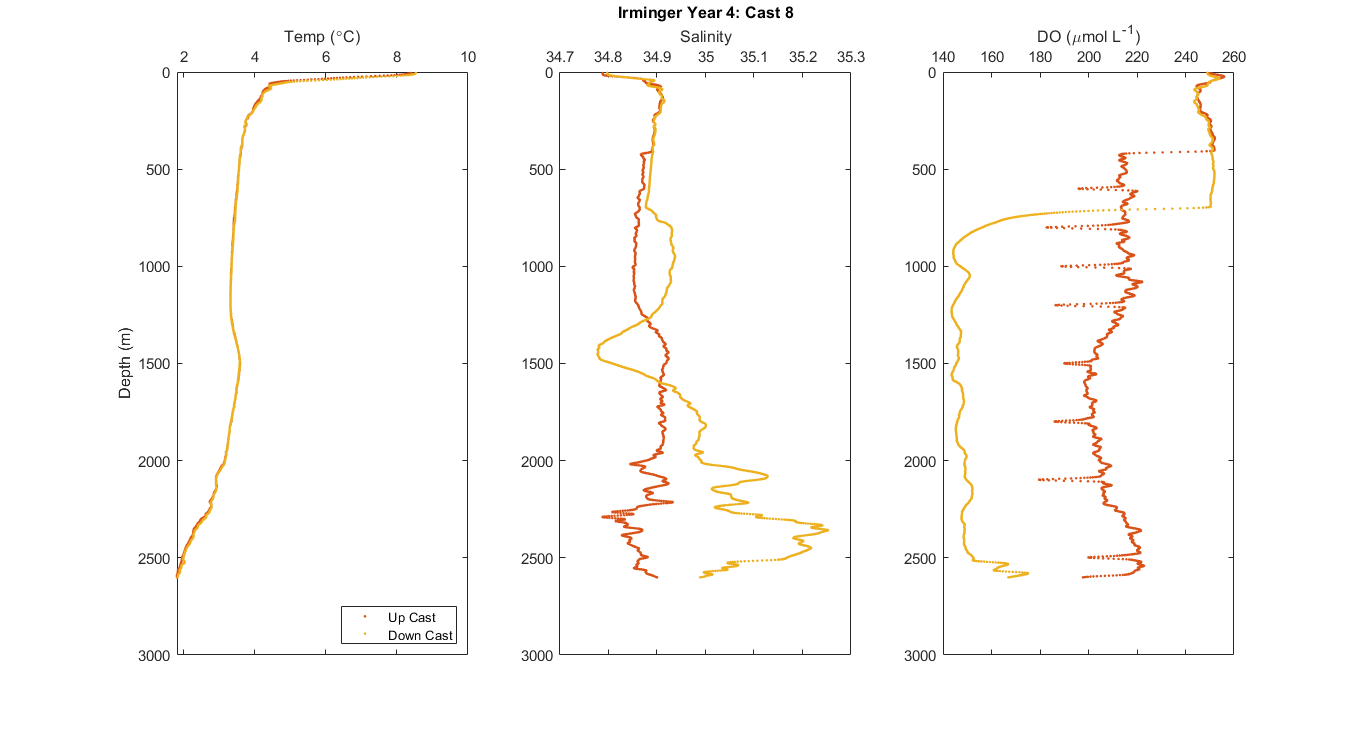

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(AR21008up.t090C,AR21008up.depSM,'.','Color',red);
hold on
plot(AR21008down.t090C,AR21008down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(AR21008up.sal00,AR21008up.depSM,'.','Color',red);
hold on
plot(AR21008down.sal00,AR21008down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 4: Cast 8')

s3 = subplot(1,3,3);
plot(AR21008up.sbeox0MLL*44.661,AR21008up.depSM,'.','Color',red);
hold on
plot(AR21008down.sbeox0MLL*44.661,AR21008down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

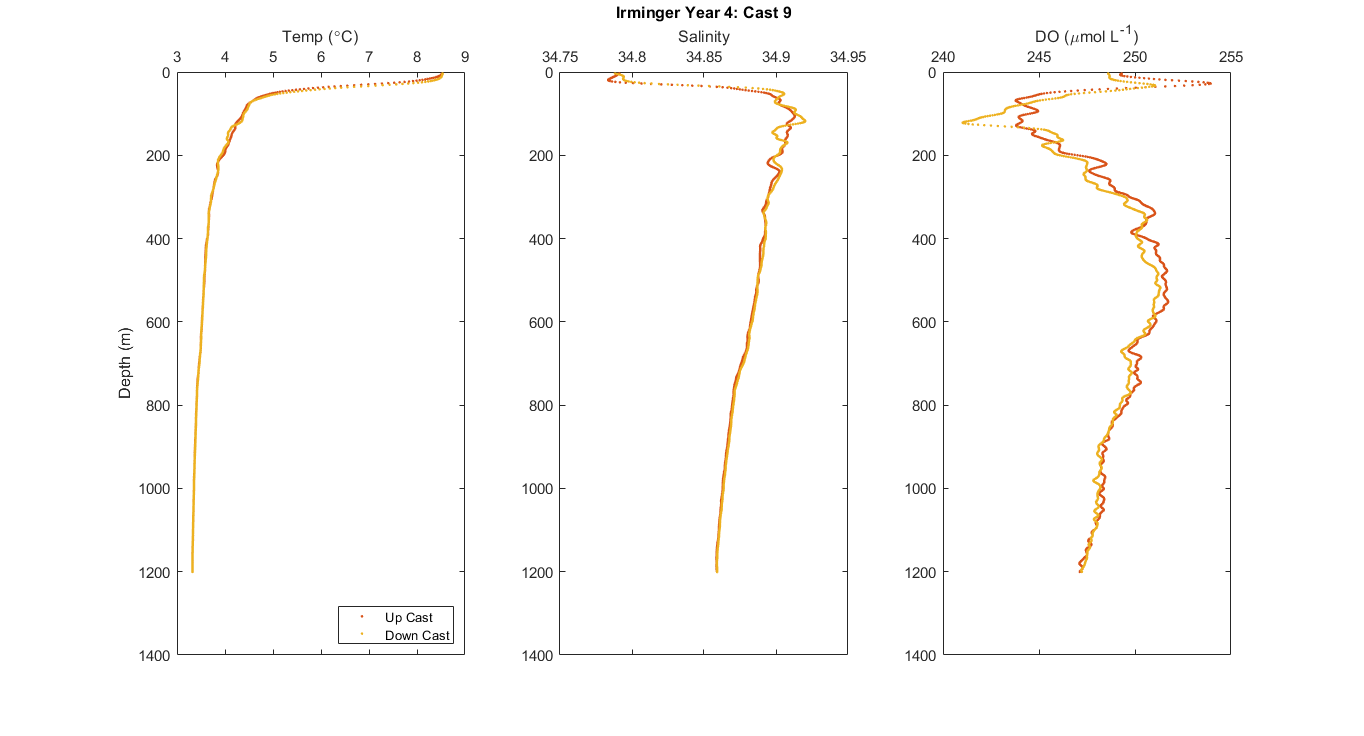


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(AR21009up.t090C,AR21009up.depSM,'.','Color',red);
hold on
plot(AR21009down.t090C,AR21009down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(AR21009up.sal00,AR21009up.depSM,'.','Color',red);
hold on
plot(AR21009down.sal00,AR21009down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 4: Cast 9')

s3 = subplot(1,3,3);
plot(AR21009up.sbeox0MLL*44.661,AR21009up.depSM,'.','Color',red);
hold on
plot(AR21009down.sbeox0MLL*44.661,AR21009down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

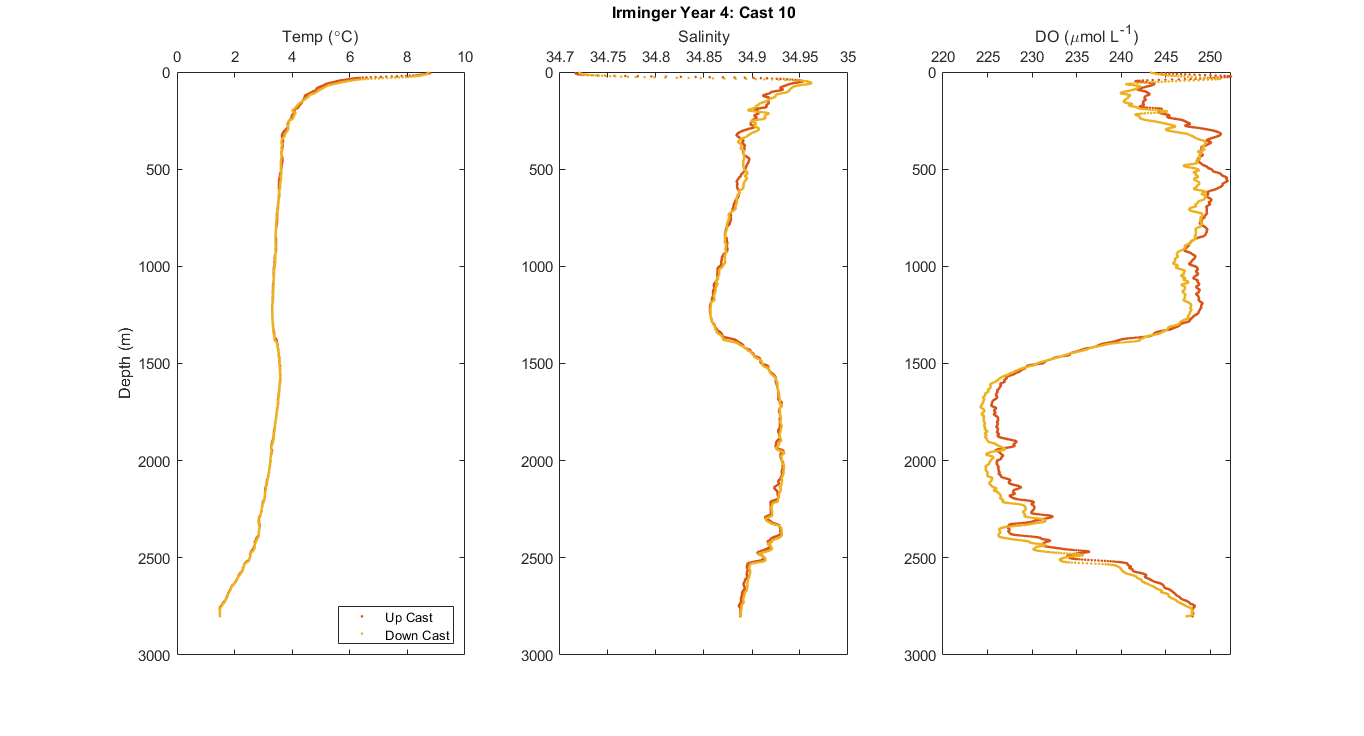


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(AR21010up.t090C,AR21010up.depSM,'.','Color',red);
hold on
plot(AR21010down.t090C,AR21010down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(AR21010up.sal00,AR21010up.depSM,'.','Color',red);
hold on
plot(AR21010down.sal00,AR21010down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 4: Cast 10')

s3 = subplot(1,3,3);
plot(AR21010up.sbeox0MLL*44.661,AR21010up.depSM,'.','Color',red);
hold on
plot(AR21010down.sbeox0MLL*44.661,AR21010down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

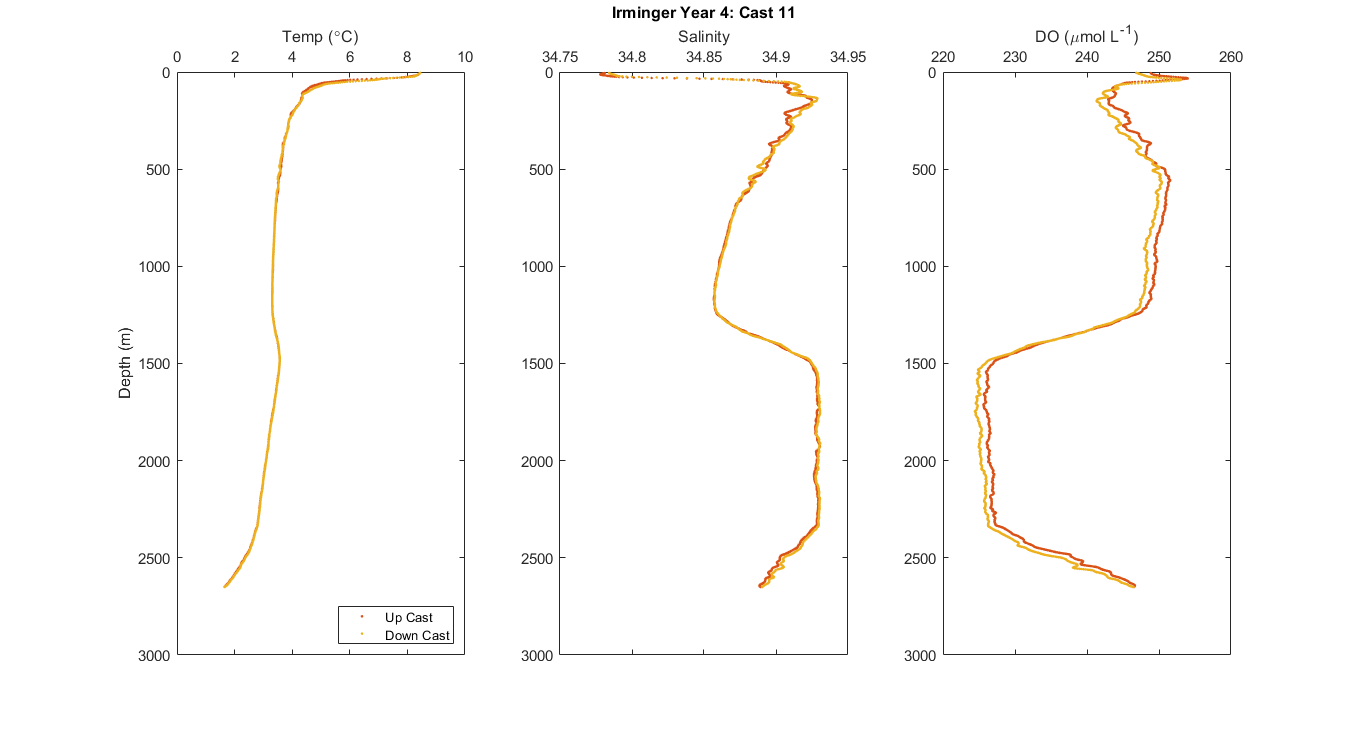


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(AR21011up.t090C,AR21011up.depSM,'.','Color',red);
hold on
plot(AR21011down.t090C,AR21011down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(AR21011up.sal00,AR21011up.depSM,'.','Color',red);
hold on
plot(AR21011down.sal00,AR21011down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 4: Cast 11')

s3 = subplot(1,3,3);
plot(AR21011up.sbeox0MLL*44.661,AR21011up.depSM,'.','Color',red);
hold on
plot(AR21011down.sbeox0MLL*44.661,AR21011down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

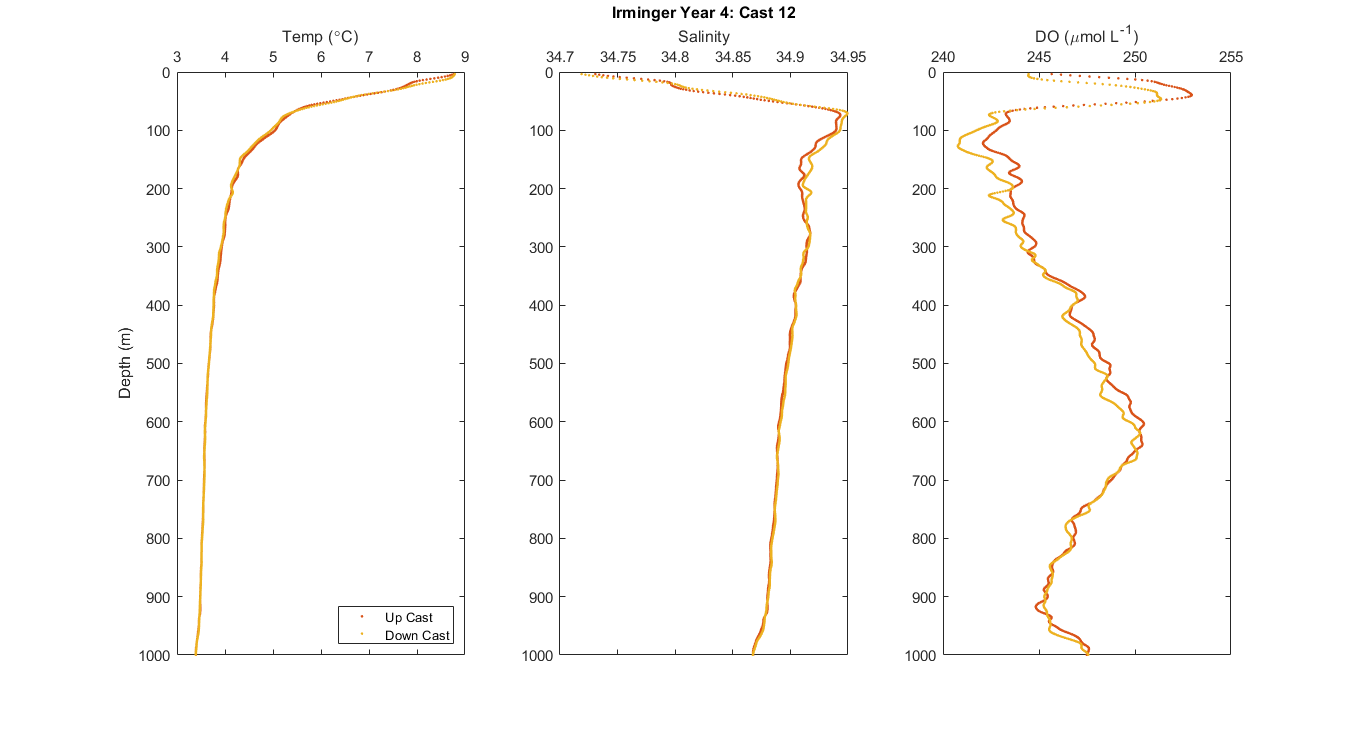


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(AR21012up.t090C,AR21012up.depSM,'.','Color',red);
hold on
plot(AR21012down.t090C,AR21012down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(AR21012up.sal00,AR21012up.depSM,'.','Color',red);
hold on
plot(AR21012down.sal00,AR21012down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 4: Cast 12')

s3 = subplot(1,3,3);
plot(AR21012up.sbeox0MLL*44.661,AR21012up.depSM,'.','Color',red);
hold on
plot(AR21012down.sbeox0MLL*44.661,AR21012down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')